# **LAB SESSION 06**

## **Introdction to Discrete Random Variables, Probability Mass Function & Cumulative Distribution Function.**

**Objective:** To familiarized with random variables, its types, Probability Mass Function (PMF), Cumulative Distribution Function (CDF) and its implementation in MATLAB

**Introduction:**

    **Random Variable:**

    A random variable is a function that associates a Real# with each element in a Sample Space of an Experiment.

    Capital Letters are used to denote Random Variables.

    Smaller Letters represent the Real# values of Random Variables.

    For Example:

- **X**: {x1 , x2 , x3 , x4}        

- **Y**: {y1 , y2 , y3 , y4}      where, y1,y2,y3,y4 are Real#s

    More than one outcomes of experiment can be mapped to the same Real# Value of the Random Variable.

    There are two types a Random Variable;

- Discrete Random Variable

- Continuous Random Variable

1.**    Discrete Random Variable:**

    A Random Variable that has a Finite of Countable Infinite number of values.

    For Example:

- 1st buss leaves @ 7:00

- 2nd buss leaves @ 7:15

1.**    Continuous Random Variable:**

    A Random Variable that has an Interval of Uncountable Infinite number of values.

    For Example:

- 4 buss leaves b/w 7:00 & 7:15

- CGPA

The Discrete Random Variable has two types of functions:

    1. Probability Mass Function (PMF)

    2. Cumulative Distribution Function (CDF)

1.**    PROBABILITY MASS FUNCTION:**

    The PMF provides the probability of a particular point in a Sample Space of a Discrete Random Variable.

For a DRV ''X'' with possible outcomes {x1,x2,x3,....,xn}, a PMF is a function such that


$$f_X \left(x_i \right)\ge 0$$



$$\sum_{i=1}^n f_X \left(x_i \right)=1$$



$$f_X \left(x_i \right)=P\left(X=x_i \right)$$


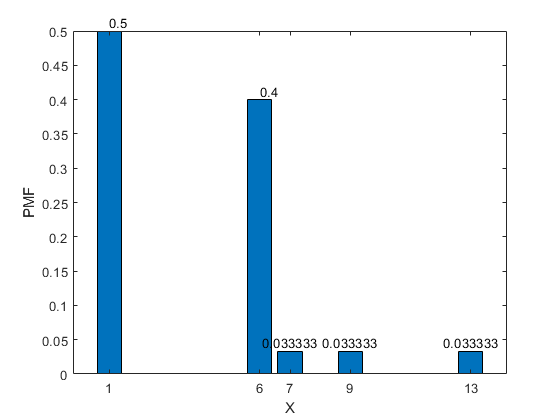

%PMF
clear all
clc
S = input('Enter the Sample Space of Discrete Ramdom Variable "X":\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.Variable Name (e.g: S) %for Pre-Defined Variable%\n X = ');
%S = [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,6,6,6,6,6,6,6,6,6,6,6,6,7,9,13];
S = sort(S);

IP = input('Enter the Event for PMF :\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.SampleSpace (i.e: S) %for SampleSpace self%\n ');
IP = sort(IP);

i = 1;
ptr = 1;
Count = 1;

while (ptr <= length(IP))
    
    for j = (1+ptr):length(IP)
        
        if IP(ptr) == IP(j)
            Count = Count + 1;
        end
        
    end
    X(i) = IP(ptr);
    ptr = ptr + Count;
    Count = 1;
    i = i + 1;
end

for i = 1:length(X)
    Count = 0;
    for j = 1:length(S)
        if X(i) == S(j)
            Count = Count + 1;
        end
    end
    PMF(i) = Count/length(S);
end

bar(X,PMF)
text(X,PMF,num2str(PMF'),'HorizontalAlignment','center','Vertic','bottom')
xlabel('X')
ylabel('PMF')

2.**    CUMULATIVE DISTRIBUTION FUNCTION:**

    The CDF provides the probability of a Range in a Sample Space of a Discrete Random Variable.

For a DRV ''X'' with possible outcomes {x1,x2,x3,....,xn}, a CDF is a function such that


$$F_X \left(x_i \right)=P\left(X=x_i \right)$$


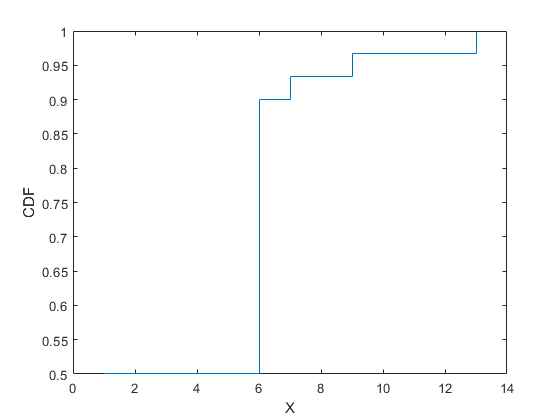

%CDF
clear all
clc
S = input('Enter the Sample Space of Discrete Ramdom Variable "X":\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.Variable Name (e.g: S) %for Pre-Defined Variable%\n X = ');
%S = [2,1,1,0,4,4,5];

IP = input('\nEnter the Index "i" from which the CDF is to be calculated:\n     1.Scalar (e.g: 9)\n<or> 2.Variable Name (e.g: Ptr) %for Pre-Defined Variable%\n i = ');
IP = S(IP);
IP = min(S):IP;

i = 1;
ptr = 1;
Count = 1;

while (ptr <= length(IP))
    
    for j = (1+ptr):length(IP)
        
        if IP(ptr) == IP(j)
            Count = Count + 1;
        end
        
    end
    X(i) = IP(ptr);
    ptr = ptr + Count;
    Count = 1;
    i = i + 1;
end

for i = 1:length(X)
    Count = 0;
    for j = 1:length(S)
        if X(i) == S(j)
            Count = Count + 1;
        end
    end
    PMF(i) = Count/length(S);
    CDF(i) = sum(PMF);
end

stairs(X,CDF)
xlabel('X')
ylabel('CDF')

**TASK # 1**

**Find PMF and CDF of the given sample space. Also plot the PMF and CDF.**

**S = [ 0 1 2 3 4 5]**

**S = [2 1 1 0]**

**Results:**

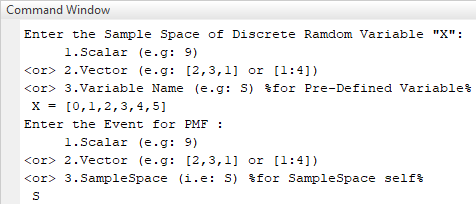

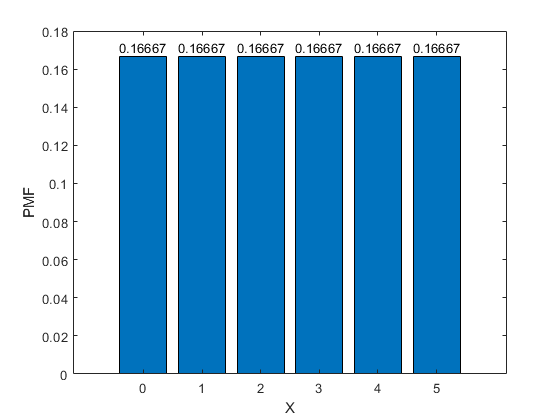

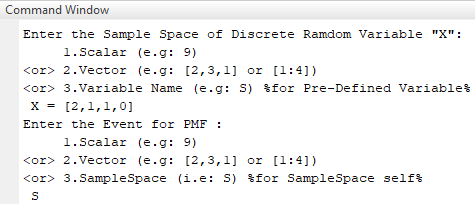

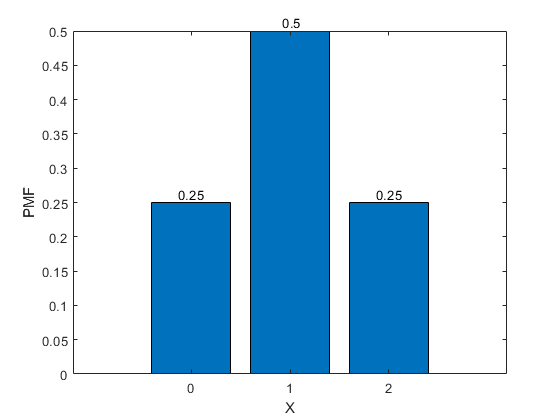

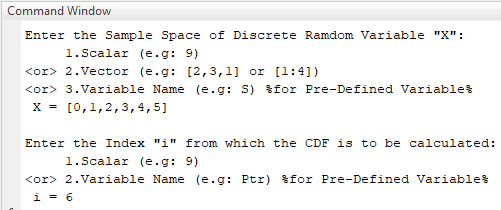

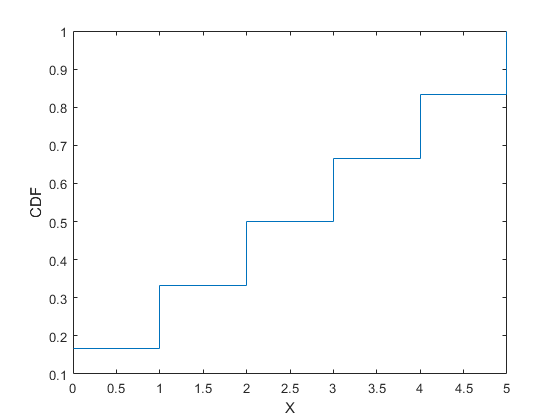

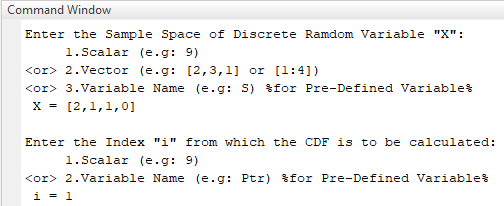

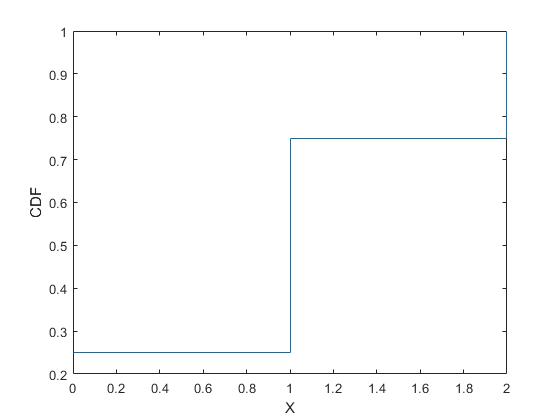

**EXPECTED/MEAN Value of Discrete Random Variable:**

    The expected value or mean value of a DRV is the average value of the Discrete Random Variable.


$$E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i P\left(X=x_i \right)$$


**Varience of Discrete Random Variable:**

    Varience is the measurement of the spread between the numbers in a data set. it measures how far each number in the set is from the mean value.


$$\mathrm{Var}\left\lbrack X\right\rbrack =\sigma^2 =\sum_{i=1}^n {\left(x_i -E\left\lbrack X\right\rbrack \right)}^2 P\left(X=x_i \right)$$


**Standard Deviation of Discrete Random Variable:**

    The square root of the varience of a DRV is the standard deviation of the Discrete Random Variable.


$$\mathrm{SD}\left\lbrack X\right\rbrack =\sigma =\sqrt{\mathrm{Var}\left\lbrack X\right\rbrack }$$


%MEAN of PMF
% 1) From Discrete Random Variables and Probability Matrix.
X = [1 , 6 , 7 , 9 , 13]
PMF = [0.5 , 0.4 , 0.033 , 0.033 , 0.033]

for i = 1:length(PMF)
    E(i) = X(i) * PMF(i);
end
disp('Expected/Mean Value of DRV is')
E = sum(E)
for i = 1:length(PMF)
    Var(i) = ( ( X(i)-E )^2 ) * PMF(i);
end
disp('Variance of DRV is')
Var = sum(Var)
disp('Standard Deviation Value of DRV is')
SD = sqrt(Var)

% 2) From Discrete Random Variable Sample Space.
clear all
clc
S = input('Enter the Sample Space of Discrete Ramdom Variable "X":\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n<or> 3.Variable Name (e.g: S) %for Pre-Defined Variable%\n X = ');
%S = [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,6,6,6,6,6,6,6,6,6,6,6,6,7,9,13];
S = sort(S);

IP = input('Enter the Probabitities:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n P = ');
IP = sort(IP);

i = 1;
ptr = 1;
Count = 1;

while (ptr <= length(IP))
    
    for j = (1+ptr):length(IP)
        
        if IP(ptr) == IP(j)
            Count = Count + 1;
        end
        
    end
    X(i) = IP(ptr);
    ptr = ptr + Count;
    Count = 1;
    i = i + 1;
end

for i = 1:length(X)
    Count = 0;
    for j = 1:length(S)
        if X(i) == S(j)
            Count = Count + 1;
        end
    end
    PMF(i) = Count/length(S);
end

for i = 1:length(PMF)
    E(i) = X(i)*PMF(i);
end
disp('Expected/Mean Value of DRV is')

Expected/Mean Value of DRV is


E = sum(E)

E = 0

for i = 1:length(PMF)
    Var(i) = ( ( X(i)-E )^2 ) * PMF(i);
end
disp('Variance of DRV is')

Variance of DRV is


Var = sum(Var)

Var = 0

disp('Standard Deviation Value of DRV is')

Standard Deviation Value of DRV is


SD = sqrt(Var)

SD = 0

**TASK # 3**

**Find the Mean, Varience and Standard Deviation of following grapfs with MATLAB**

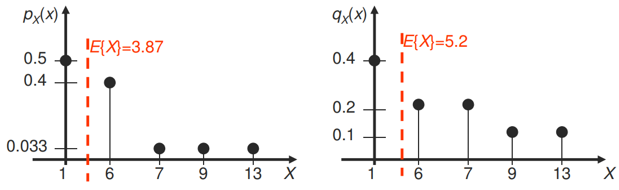

**Results:**

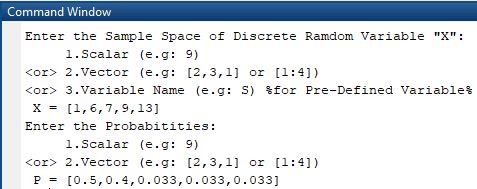

`Expected/Mean Value of DRV is`

`E = 0`

`Variance of DRV is`

`Var = 0`

`Standard Deviation Value of DRV is`

`SD = 0`

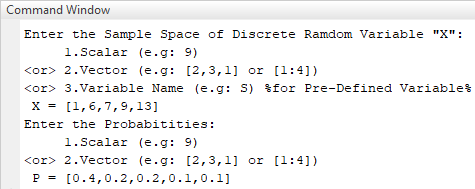

`Expected/Mean Value of DRV is`

`E = 0`

`Variance of DRV is`

`Var = 0`

`Standard Deviation Value of DRV is`

`SD = 0`